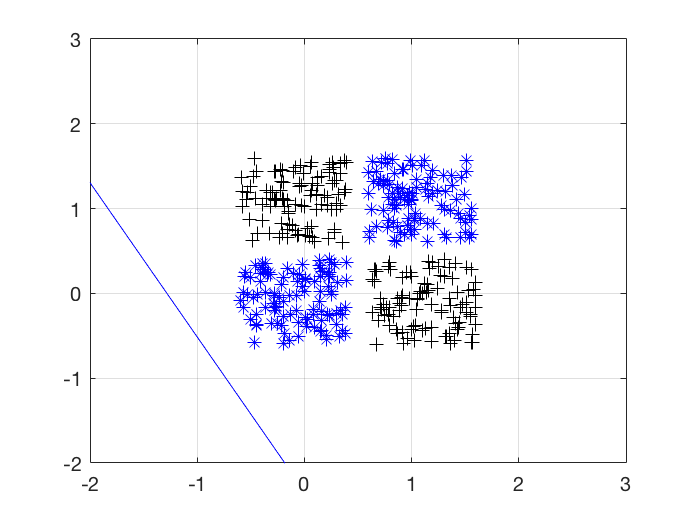

close all, clear all clc
% number of samples of each cluster
K = 100;
% offset of clusters
q = .6;
% define 2 groups of input data
A1 = [rand(1,K)-q; rand(1,K)+q]; B1 = [rand(1,K)+q; rand(1,K)+q]; C1 = [rand(1,K)+q; rand(1,K)-q]; D1 = [rand(1,K)-q; rand(1,K)-q]; A = [A1 C1];
B = [B1 D1];
% plot data
plot(A(1,:),A(2,:),'k+',B(1,:),B(2,:),'b*')
xlim([-2,3]);
ylim([-2,3]);
grid on
hold on

% coding (+1/0) for 2-class XOR problem
a = 0; b = 1;
% define inputs (combine samples from all two classes)
P = [A B];
% define targets
T = [repmat(a,1,length(A)) repmat(b,1,length(B))];
net = perceptron;
% To see the adaptation you need to look at the plot while the code is running
E = 1;
net.adaptParam.passes = 1;
linehandle = plotpc(net.IW{1},net.b{1});
n = 0;
while (sse(E) & n<20) % sse: Sum squared error or mae: mean absolute error
    n = n+1;
    [net,Y,E] = adapt(net,P,T);
    linehandle = plotpc(net.IW{1},net.b{1},linehandle); drawnow;
    pause(2); % 2 seconds pause
end

% show perceptron structure
view(net);